# Auslegung einer Traktionsbatterie für Bahnstrecken

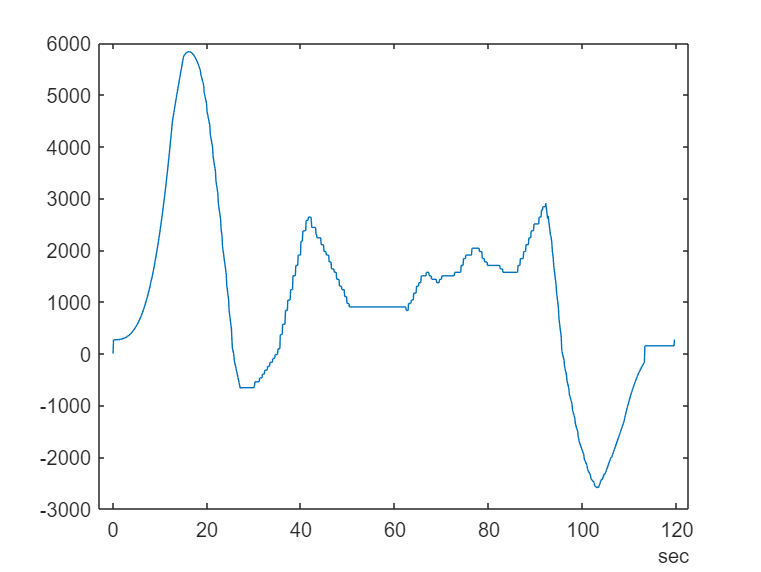

% Dieses Skript dient dazu, Traktionsbatterien für Bahnstrecken, auf
% Grundlage einer Fahrtsimulation der Strecke, auszulegen. 

% Eingabe, welcher Prozentsatz der Leistung gedeckt werden soll: 
% (CR = cover ratio)
CR = input("Geben Sie den gewünschten Deckungsgrad in % ein: "); % Cover Ratio in %

% Zunächst werden die benötigten Inputs der Strecken und des gewünschten
% Fahrzeuges geladen:
Streckenparameter2;
Import_track_ZLR_Data;

% Eingabe der gewünschten Strecke:
Str = input("Geben Sie die gewünschte Strecke ein: "); % ST_ZH, HB_ZH, ZH_HB, ZH_ST

% Eingabe des gewünschten Fahrzeuges: 
FZ = input("Geben Sie den gewünschten Zugtypen ein: "); % KISS, RE450 etc.

% Eingabe der Fahrtzeit: (Diese sollte ungefähr der realen Fahrtzeit
% entsprechen (2 oder 3 min oder mit Verspätung < 2min)
Fahrtzeit = input("Geben Sie die gewünschte Fahrtzeit in Sekunden ein: "); % [s] Fahrtzeit kann manuell angepasst werden


% Benötigte Berechnungen für Geschw. und Bremspunkte werden berechent für
% die Strecke
Optimization4;

% Durchführung der Simulation
SimulationAuslegungTraktionsbatterie;

## Berechnung der Leistung um CR einzusparen: Kontinuierlicher Ansatz

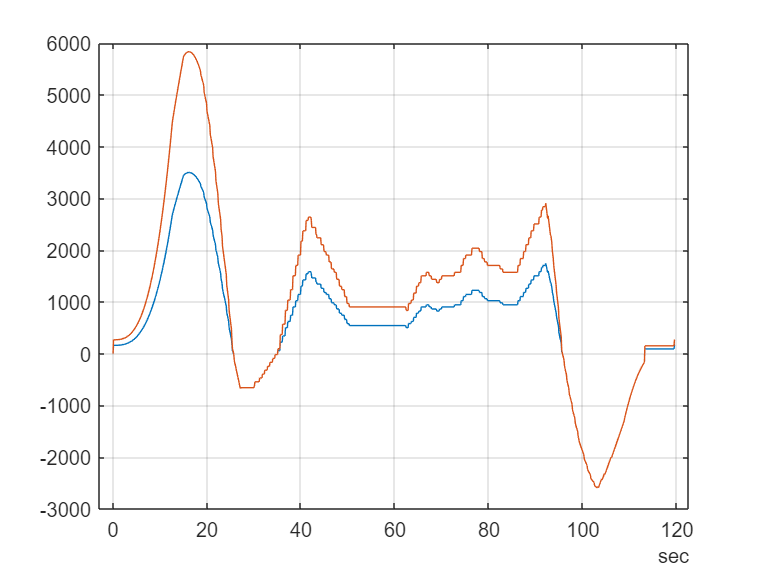

cla reset
% Es wird die neue Leistungskurve mit dem festgesetzten Prozentsatz an zu
% deckender Leistung berechnet
for i = 1:length(CompData.Leistung)
    if (CompData.Leistung(i) > 0)
        P(i,1) = CR/100 * CompData.Leistung(i);
        P(i,2) = CompData.Leistung(i) - P(i,1);
    else
        P(i,1) = 0;
        P(i,2) = CompData.Leistung(i);
    end
end

plot(CompData.time, P(:,2), CompData.time, CompData.Leistung)
grid()


% Das maximum der Differenz der beiden Kennlinien kann verwendet werden, um
% die maximale Leistung, welche für die Deckung benötigt wird zu bestimmen.
PDiff = CompData.Leistung - P(:,2);
PBatCont = max(PDiff)

PBatCont = 2.3331e+03


% Die Differenz der Energie beider Kennlinien wird verwendet, um die
% Kapazität der Batterie zu bestimmen.
EBatCont = sum(const.dt * P(:,1))

EBatCont = 6.5850e+04

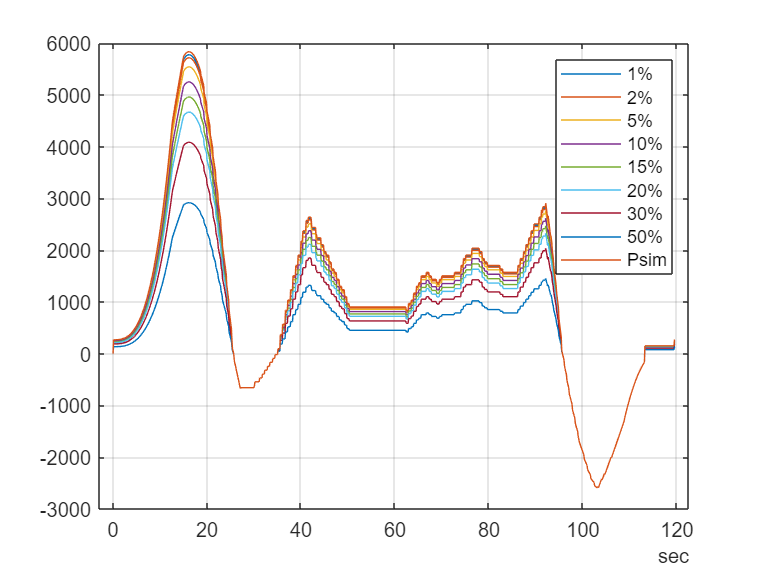


% Es werden automatisch verschiedene Prozentsätze berechnet und danach
% miteinander verglichen.
%CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3, 0.35, 0.4, 0.45, 0.5]; % zu berechnende Prozentsätze
CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.3, 0.5];

for n = 1:length(CRset)
    for i = 1:length(CompData.Leistung)
        if (CompData.Leistung(i) > 0)
            P(i,n) = CRset(n) * CompData.Leistung(i);
            Psub(i,n) = CompData.Leistung(i) - P(i,n);
        else
            P(i,n) = 0;
            Psub(i,n) = CompData.Leistung(i);
        end
    end
    PDiff(:,n) = CompData.Leistung - Psub(:,n);
    PBatCont(:,n) = max(PDiff(:,n));
    EBatCont(n) = sum(const.dt * P(:,n));   
end
    
% Darstellung der neuen Leistungsverläufe
plot(CompData.time, Psub(:,:), CompData.time, CompData.Leistung)
legendString = [string(CRset * 100) + "%" "Psim"];
legend(legendString)
grid()

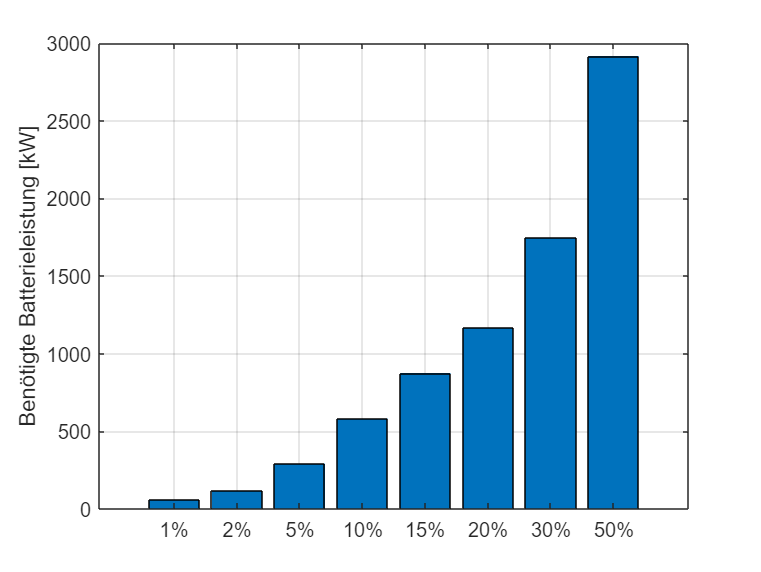


% Darstellung der benötigten Batterieleistungen für das Erreichen der
% Einsparungen
bar(PBatCont)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batterieleistung [kW]")
grid()

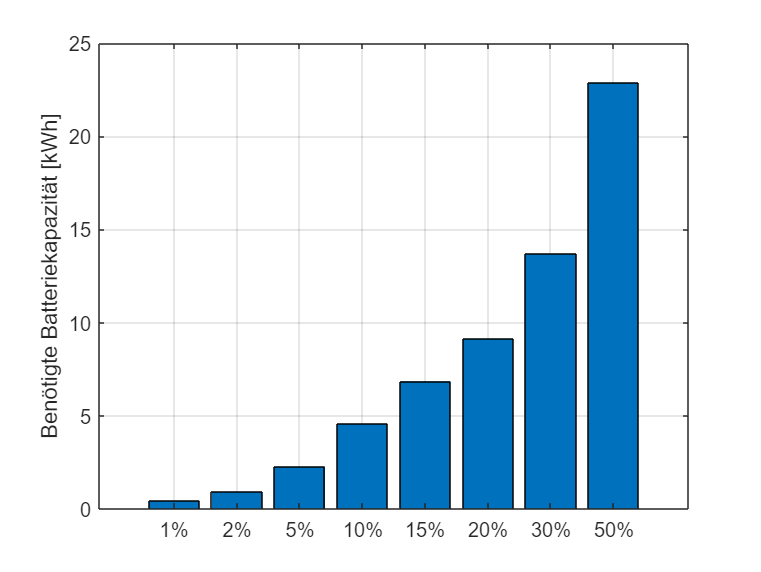


% Darstellung der benötigten Batteriekapazität (Energie)
bar(EBatCont/1000/3.6)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batteriekapazität [kWh]")
grid()

## Berechnung der Leistung um CR einzusparen: Spitzendeckender Ansatz

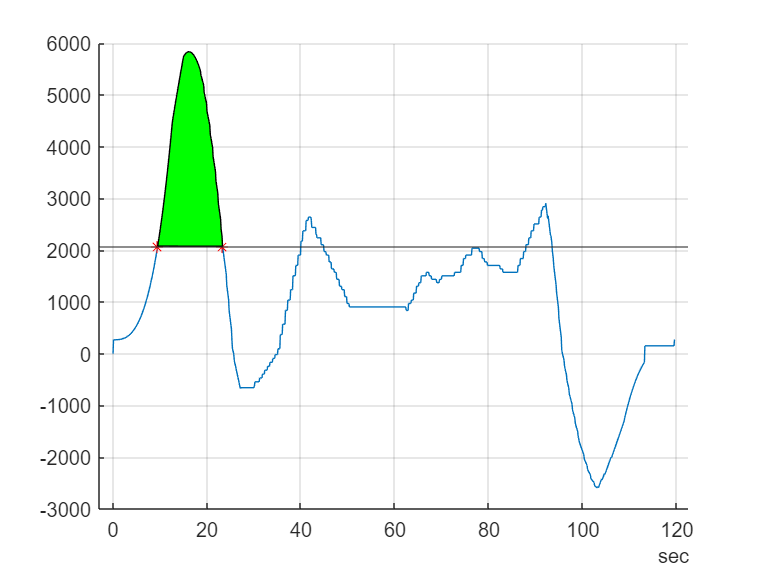

cla reset
% Berechnung der Gesamtfläche:
% Es wird das Matlab Package "Fast and Robust Curve Intersections" von
% Douglas Schwarz benötigt.

for i = 1:length(CompData.Strecke)
    if (CompData.Leistung(i) > 0)
        Etot(i,1) = CompData.Energie(i);
    else
        Etot(i,1) = 0;
    end
end
ETOT = sum(Etot);

inters = max(CompData.Leistung)-10; % the intersection line

EBatPeak = 0;

while (ETOT * CR/100 > EBatPeak)

    inters = inters - 1;
    [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters inters]);
    xlin = round(xlin);

    EBatPeak = sum(CompData.Leistung(xlin(1):xlin(2))-inters)*const.dt;

end

hold on
plot(CompData.time, CompData.Leistung)
plot(CompData.time(xlin(1)),ylin(1),'r*', CompData.time(xlin(2)), ylin(2),'r*')
yline(inters)
fill(CompData.time(xlin(1):xlin(2)), CompData.Leistung(xlin(1):xlin(2)), 'g')
grid()

cla reset

% Die benötigte Batterieleistung kann nun berechnet werden, um die
% berechnete Leistungsspitze zu decken.
PBatPeak = max(CompData.Leistung) - inters;

% Ebenfalls kann die benötigte Energie, welche für die Deckung benötigt
% wird berechnet werden:
EBatPeak

EBatPeak = 3.2935e+04

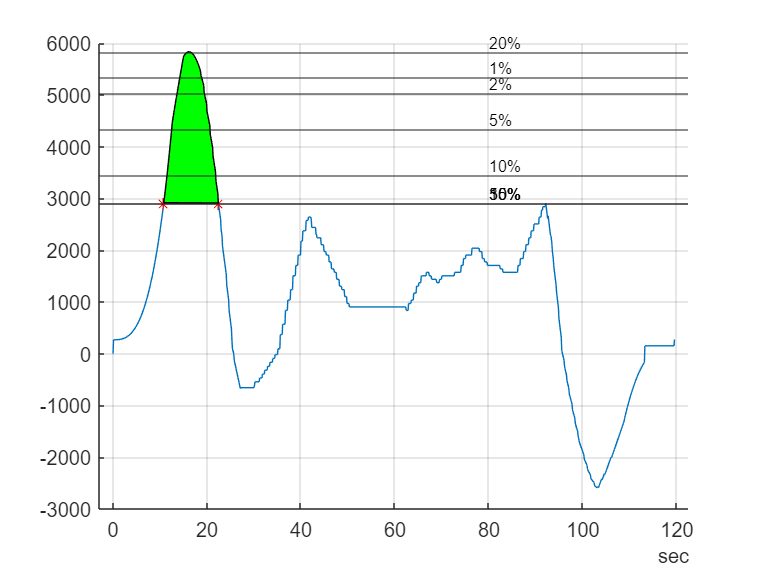


% Es werden automatisch verschiedene Prozentsätze berechnet und danach
% miteinander verglichen.
%CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3, 0.35, 0.4, 0.45, 0.5]; % zu berechnende Prozentsätze
CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.3, 0.5];

inters(1:length(CRset)) = max(CompData.Leistung)-10;

EBatPeak(1:length(CRset)) = 0;

% for n = 1:length(CRset)
%     EBatPeak(n) = 0;
%     while (ETOT * CRset(n) > EBatPeak)
% 
%         inters(n) = inters(n) - 1;
%         [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters(n) inters(n)]);
%         xlin = round(xlin);
% 
%         EBatPeak(n) = sum(CompData.Leistung(xlin(1):xlin(2))-inters(n))*const.dt;
%         PBatPeak(n) = max(CompData.Leistung) - inters(n);
% 
%     end
% end

for n = 1:length(CRset)
    EBatPeak(n) = 0;

    while (ETOT * CRset(n) > EBatPeak)
        inters(n) = inters(n) - 1;
        [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters(n) inters(n)]);
        xlin = round(xlin);

        if(length(xlin) > 2)

            for i = 1:2:length(xlin)

                EBatPeak(n) = EBatPeak(n) + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters(n))*const.dt;

            end
            
        else
            EBatPeak(n) = sum(CompData.Leistung(xlin(1):xlin(2))-inters(n))*const.dt;
        end

        PBatPeak(n) = max(CompData.Leistung) - inters(n);
        
    end
end

hold on
plot(CompData.time, CompData.Leistung)
plot(CompData.time(xlin(1)),ylin(1),'r*', CompData.time(xlin(2)), ylin(2),'r*')
yline(inters)
fill(CompData.time(xlin(1):xlin(2)), CompData.Leistung(xlin(1):xlin(2)), 'g')
grid()
text(ones(length(inters),1)*80 , inters + 180, [string(CRset * 100) + "%"],"FontSize",8)

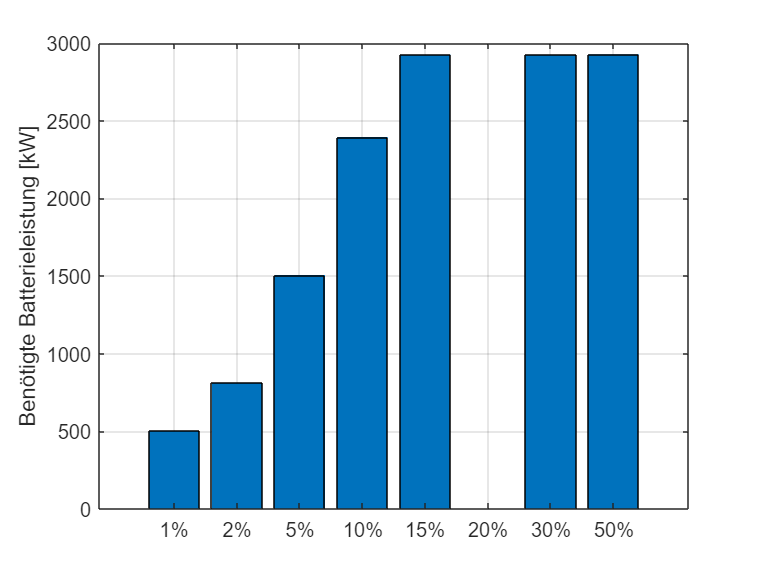

cla reset

% Darstellung der benötigten Batterieleistungen für das Erreichen der
% Einsparungen
bar(PBatPeak)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batterieleistung [kW]")
grid()

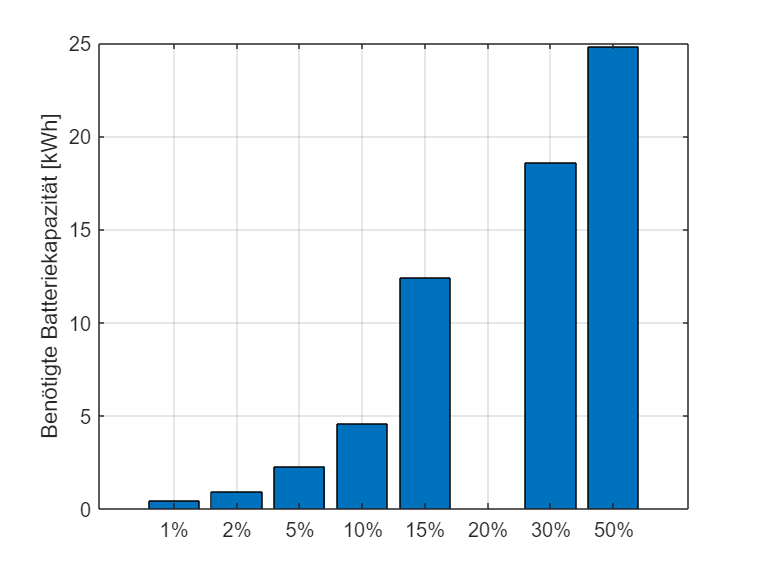


% Darstellung der benötigten Batteriekapazität (Energie)
bar(EBatPeak/1000/3.6)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batteriekapazität [kWh]")
grid()


load('BatterieAuslegung')

BatteryDimensions.(Str.id).CRset = CRset;
BatteryDimensions.(Str.id).EBatCont = EBatCont;

Unrecognized function or variable 'EBatCont'.

BatteryDimensions.(Str.id).EBatPeak = EBatPeak;
BatteryDimensions.(Str.id).ETOT = ETOT;
BatteryDimensions.(Str.id).inters = inters;
BatteryDimensions.(Str.id).PBatCont = PBatCont;
BatteryDimensions.(Str.id).Psub = Psub;
BatteryDimensions.(Str.id).PBatPeak = PBatPeak;

save('BatterieAuslegung', 'BatteryDimensions')

% save('BatterieDatenZH_HB', 'CRset', 'EBatCont', 'EBatPeak', 'ETOT', 'inters', 'PBatCont', 'PBatPeak')